# Lab - Initial value problems 4

**Topics: **Implicit & Explicit Euler

## Pendulum problem

clear, clc, format compact


$$\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\theta =0$$


Compute the period for a 1-meter pendulum with the initial conditions $\theta =\frac{\pi }{8}\;\textrm{and}\;\frac{d\theta }{\textrm{dt}}=0$

g = 9.81;
L = 1;

theta0 = pi/8;
omega0 = 0;
Y0 = [theta0,omega0];


### Analytical solution

syms theta(t)
dtheta = diff(theta);
ode = diff(theta, t, 2) + g/L*theta == 0;

cond1 = theta(0) == theta0;
cond2 = dtheta(0) == omega0;
conds = [cond1,cond2];

solution(t) = dsolve(ode,conds)

$$solution(t) = \frac{\pi \,\cos\left(\frac{3\,\sqrt{109}\,t}{10}\right)}{8}$$

### Solve using ode45

opts = odeset('Events',@endevent);
[t,Yode] = ode45(@pendelum, [0 inf],Y0,opts, L);
tf = 4*t(end)

tf = 2.0059

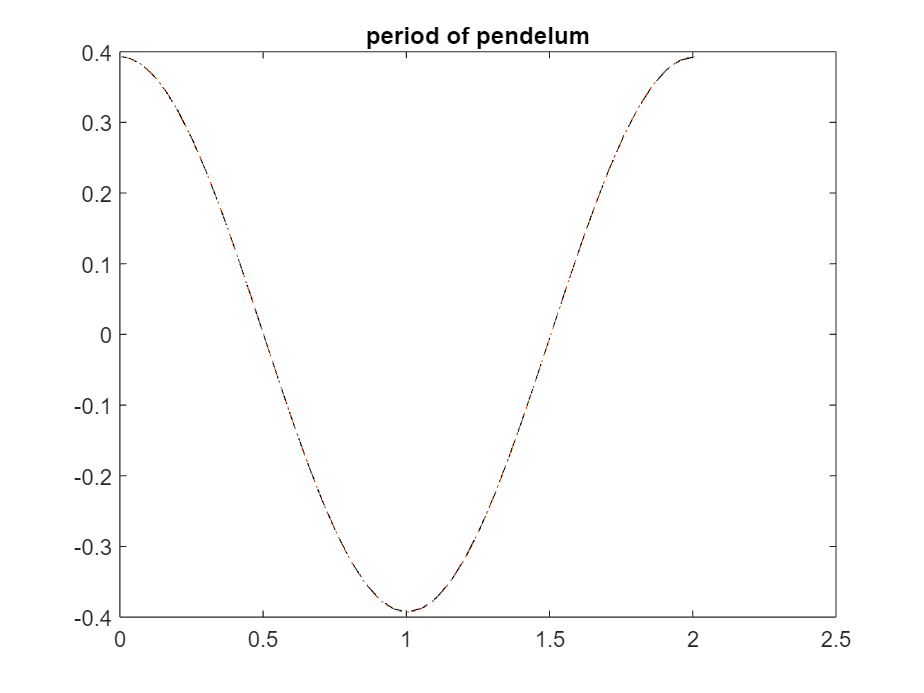

[t,Yode] = ode45(@pendelum, [0 tf],Y0,[], L);
figure()
plot(t, Yode(:,1),'k--')
title 'period of pendelum'
hold on
fplot(solution, [0,tf],':')

### Solve using explicit Euler

$\begin{array}{l}
Y_{i+1} =\left(I+\textrm{Ah}\right)Y_i \\
A=\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{L} & 0
\end{array}\right\rbrack 
\end{array}$h= 0.1, 1st five values

h = 0.1;
A = [0   1;
    -g/L 0];

M = eye(2) + A*h;

Y1 = M*Y0';
Y2 = M*Y1;
Y3 = M*Y2;
Y4 = M*Y3;
Y5 = M*Y4;

Y = [Y1,Y2,Y3,Y4,Y5]'

Y =     0.3927   -0.3852
    0.3542   -0.7705
    0.2771   -1.1179
    0.1653   -1.3898
    0.0264   -1.5520


### Solve using implicit Euler


$$Y_{i+1} ={\left(I-\textrm{Ah}\right)}^{-1} Y_i$$


Yi1 = (eye(2)-A*h)\Y0'

Yi1 =     0.3576
   -0.3508


Yi2 = (eye(2)-A*h)\Y1;
Yi3 = (eye(2)-A*h)\Y2;
Yi4 = (eye(2)-A*h)\Y3;
Yi5 = (eye(2)-A*h)\Y4;

Yi = [Yi1,Yi2,Yi3,Yi4,Yi5]'

Yi =     0.3576   -0.3508
    0.3225   -0.7016
    0.2524   -1.0181
    0.1506   -1.2656
    0.0240   -1.4133


### Plotting

## HELPER FUNCTIONS

### Function modeling swinging pendulum


$$\frac{d}{\textrm{dt}}\left\lbrack Y\right\rbrack =\left\lbrack \begin{array}{c}
Y\left(2\right)\\
-\frac{g}{L}Y\left(1\right)
\end{array}\right\rbrack$$


function dY = pendelum(t, Y, L)
    g = 9.81;
    dY = [Y(2); -g/L*Y(1)];
end

### Event function to end integration

$Y=\left\lbrack \begin{array}{c}
\theta \\
\omega 
\end{array}\right\rbrack$find when $\theta =0$

function [detect, stopint, direction] = endevent(t,y, varargin)
    detect = y(1);
    stopint = 1; % Stop the integration
    direction = 0;  % 0  direction doesn't matter
end
